clear all;
close all;
clc;
%Oceanside buoy correlation
%start time is May 24 2020 06:30:00
startTime = 20200524063000;
%end time is May 25 2020 15:00:00
endTime = 20200525150000;
%load glider data
gliderTable = readtable('metbuoy_26-04.csv');
%get waveglider time and wind vectors for appropriate times
[wgt wgWind10m ~] = gliderTime(gliderTable, startTime, endTime);
%upload san nic band frequency table
freqTable = readtable('Oceanside_May2020.txt');

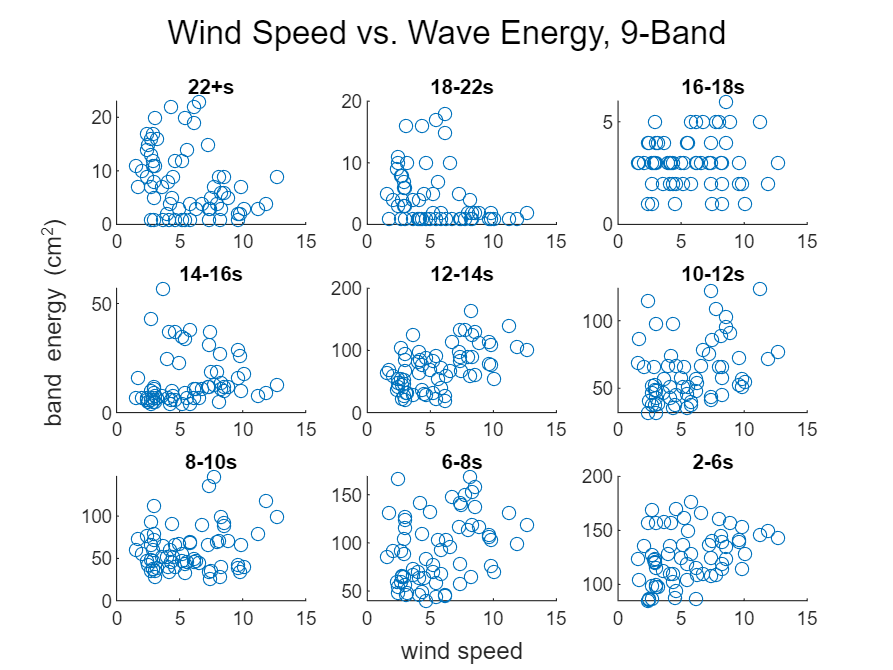

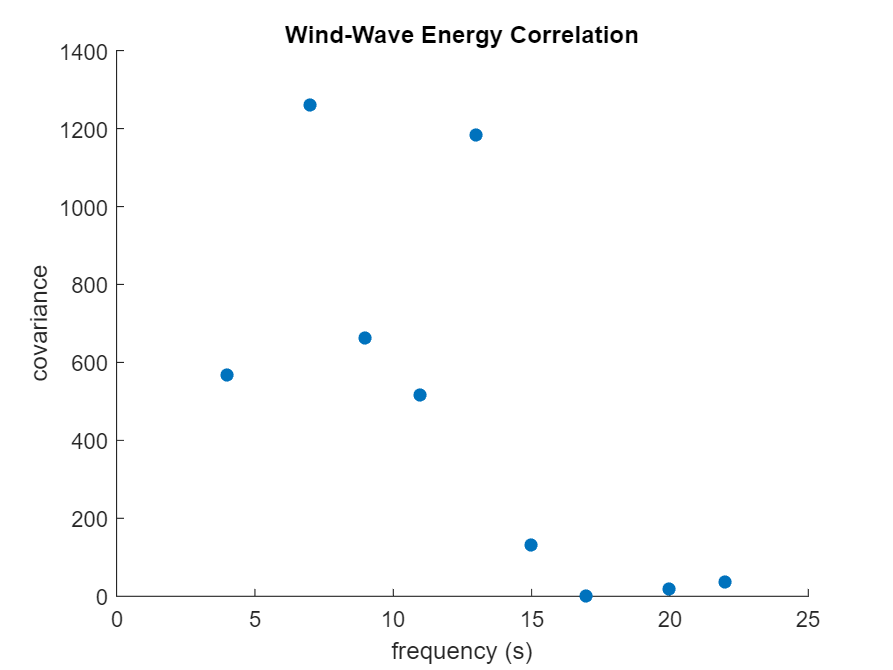

%correlation
windWaveCorr(freqTable, startTime, endTime, wgt, wgWind10m)